format long;

## Problema 1

Formula repetata a trapezului

I1 = trapezes(@sin,0,pi,10)

I1 =    1.983523537509455


I1Optim = trapezes(@sin,0,pi,1608)

I1Optim =    1.999999363825240


Formula repetata Simpson

I2 = Simpson(@sin,0,pi,10)

I2 =    2.000006784441801


I2Optim = Simpson(@sin,0,pi,19)

I2Optim =    2.000000519488672


Formula repetata a dreptunghiului

I3 = rectangles(@sin,0,pi,10)

I3 =    2.008248407907975


I3Optim = rectangles(@sin,0,pi,800)

I3Optim =    2.000001285105318


## Problema 2

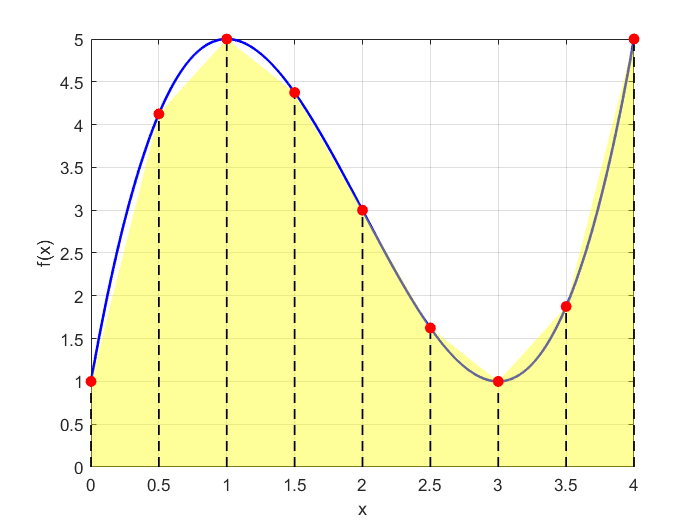

f = @(x) x.^3 - 6*x.^2 + 9*x + 1;
reprezentare_trapeze(f, 0, 4, 8);

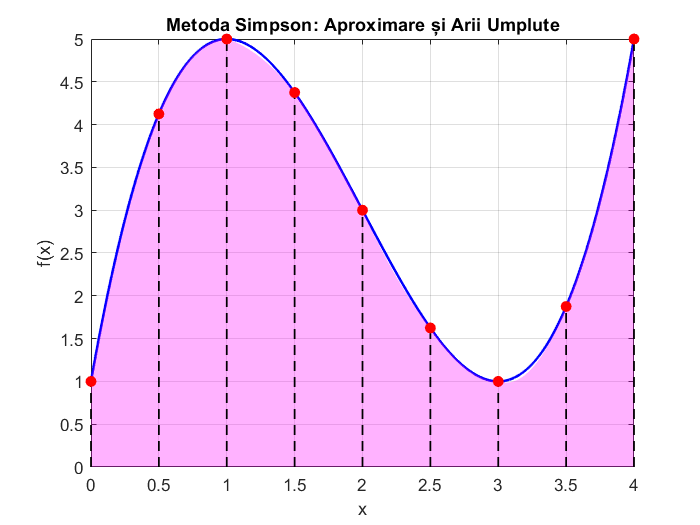

reprezentare_simpson(f, 0, 4, 8);

## Problema 4

Metoda lui Romberg

[I4,nrEval] = Romberg(@sin,0,pi,1e-6)

I4 =    2.000000000001321


nrEval =     33


## Problema 5

Implementare adquad algoritmul 1

[I5,nrEval] = adquad(@sin,0,pi,1e-6)

I5 =    1.999999999655266


nrEval =     57


function [Q,fcount] = adquad(F,a,b,tol,varargin)
    % make F callable by feval.
    if ischar(F) && exist(F)~=2
       F = inline(F);
    elseif isa(F,'sym')
       F = inline(char(F));
    end 
    
    if nargin < 4 || isempty(tol), tol = 1.e-6; end
    
    % Initialization 
    c = (a + b)/2;
    fa = F(a,varargin{:}); fc = F(c,varargin{:});
    fb = F(b,varargin{:});
    
    % Recursive call
    [Q,k] = quadstep(F, a, b, tol, fa, fc, fb, varargin{:});
    fcount = k + 3;
end

function [Q,fcount] = quadstep(F,a,b,tol,fa,fc,fb,varargin)
    h = b - a; 
    c = (a + b)/2;
    fd = F((a+c)/2,varargin{:});
    fe = F((c+b)/2,varargin{:});
    Q1 = h/6 * (fa + 4*fc + fb);
    Q2 = h/12 * (fa + 4*fd + 2*fc + 4*fe + fb);
    if abs(Q2 - Q1) <= tol
       Q  = Q2 + (Q2 - Q1)/15;
       fcount = 2;
    else
       [Qa,ka] = quadstep(F, a, c, tol, fa, fd, fc, varargin{:});
       [Qb,kb] = quadstep(F, c, b, tol, fc, fe, fb, varargin{:});
       Q  = Qa + Qb;
       fcount = ka + kb + 2;
    end
end

function [I,nfev]=Romberg(f,a,b,epsi,nmax)
    
    if nargin < 5
      nmax=10;
    end
    if nargin < 4
      epsi=1e-3;
    end
    R=zeros(nmax,nmax);
    h=b-a;
    % first iteration
    R(1,1)=h/2*(sum(f([a,b])));
    nfev=2;
    for k=2:nmax
       %trapezes formula 
       x=a+((1:2^(k-2))-0.5)*h;
       R(k,1)=0.5*(R(k-1,1)+h*sum(f(x)));
       nfev=nfev+length(x);
       %extrapolation
       plj=4;
       for j=2:k
          R(k,j)=(plj*R(k,j-1)-R(k-1,j-1))/(plj-1);
          plj=plj*4;
       end
       if (abs(R(k,k)-R(k-1,k-1))<epsi)&&(k>3)
          I=R(k,k);
          return
       end
       %halving step
       h=h/2;
    end
    error('iteration number exceeded')
end

function I = trapezes(f,a,b,n)
    h=(b-a)/n;
    I=(f(a) + f(b) + 2*sum(f((1:n-1)*h+a)))*h/2;
end

function I = Simpson(f,a,b,n)
    h=(b-a)/n;
    x2=(1:n-1)*h+a;
    x4=(0:n-1)*h+a+h/2;
    I=h/6*(f(a)+f(b)+2*sum(f(x2))+4*sum(f(x4)));
end

function I = rectangles(f,a,b,n)
    h=(b-a)/n;
    x=a+(0:n-1)*h+h/2;
    I=h*sum(f(x));
end

function reprezentare_trapeze(f, a, b, n)
    t = linspace(a, b, 1000);
    y = f(t);
    plot(t, y, 'b-', 'LineWidth', 1.5);
    hold on;
    
    x = linspace(a, b, n+1);
    fx = f(x);
    
    for k = 1:n
        X_trap = [x(k), x(k), x(k+1), x(k+1)];
        Y_trap = [0, fx(k), fx(k+1), 0];
        fill(X_trap, Y_trap, 'y', 'FaceAlpha', 0.4, 'EdgeColor', 'none');
    end
    
    
    for k = 1:length(x)
        plot([x(k), x(k)], [0, fx(k)], 'k--', 'LineWidth', 1);
    end
    
    plot(x, fx, 'ro', 'MarkerFaceColor', 'r');
    
    xlabel('x');
    ylabel('f(x)');
    grid on;
    hold off;
end
function reprezentare_simpson(f, a, b, n)
    if mod(n, 2) ~= 0
        error('n trebuie să fie par pentru metoda Simpson!');
    end
    
    % Date pentru curba funcției
    t = linspace(a, b, 1000);
    y = f(t);
    figure;
    plot(t, y, 'b-', 'LineWidth', 1.5);
    hold on;
    
    % Noduri și valori
    x = linspace(a, b, n + 1);
    fx = f(x);
    
    % Desenează aproximarea cu parabole + umplere
    for k = 1:2:n-1
        x0 = x(k);     f0 = fx(k);
        x1 = x(k + 1); f1 = fx(k + 1);
        x2 = x(k + 2); f2 = fx(k + 2);
        
        X_dom = linspace(x0, x2, 200);
        Y_parab = parabola_lagrange(X_dom, x0, x1, x2, f0, f1, f2);
        
        % Umple între axa OX și minimul dintre funcția reală și parabola
        Y_fill = max(0, min(f(X_dom), Y_parab));
        
        fill([X_dom, fliplr(X_dom)], [Y_fill, zeros(size(Y_fill))], ...
             'm', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
    
    % Delimitările verticale
    for k = 1:length(x)
        plot([x(k), x(k)], [0, fx(k)], 'k--', 'LineWidth', 1);
    end
    
    % Nodurile punctate
    plot(x, fx, 'ro', 'MarkerFaceColor', 'r');
    
    xlabel('x');
    ylabel('f(x)');
    grid on;
    hold off;
end

% Funcție auxiliară pentru parabola de interpolare Lagrange
function y_parab = parabola_lagrange(x_eval, x0, x1, x2, f0, f1, f2)
    L0 = ((x_eval - x1) .* (x_eval - x2)) / ((x0 - x1) * (x0 - x2));
    L1 = ((x_eval - x0) .* (x_eval - x2)) / ((x1 - x0) * (x1 - x2));
    L2 = ((x_eval - x0) .* (x_eval - x1)) / ((x2 - x0) * (x2 - x1));
    y_parab = f0 * L0 + f1 * L1 + f2 * L2;
end
